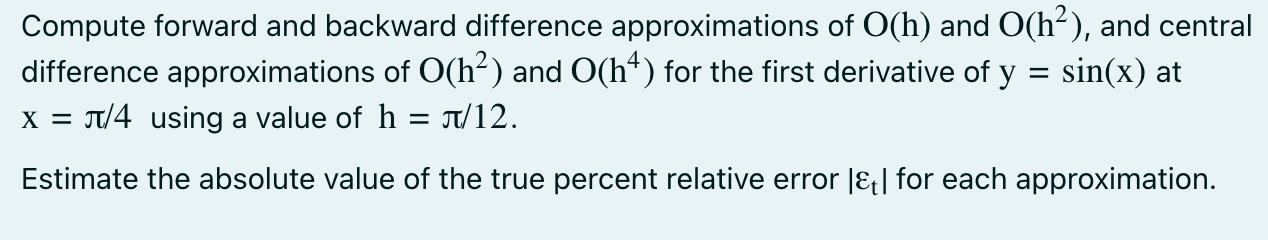

y = @(x) sin(x);
yd = @(x) cos(x);
x = pi/4;

%true_value
true_value = yd(x)

true_value = 0.7071


%approx
h = pi/12;

% forward 1
forward = (y(x + h) - y(x)) / h

forward = 0.6070

error_forward = abs(((true_value - forward) / true_value)) * 100

error_forward = 14.1538


% backward 1
backward = (y(x) - y(x - h)) / h

backward = 0.7911

error_backward = abs(((true_value - backward) / true_value)) * 100

error_backward = 11.8770


% central 1
central = (y(x + h) - y(x - h)) / (2 * h)

central = 0.6991

error_central = abs(((true_value - central) / true_value)) * 100

error_central = 1.1384


% forward high accurate
acc_forward = (-y(x + 2*h) + 4*y(x + h) - 3*y(x)) / (2*h)

acc_forward = 0.7197

error_acc_forward = abs(((true_value - acc_forward) / true_value)) * 100

error_acc_forward = 1.7867


% backward high accurate
acc_backward = ((3*y(x)-4*y(x-h)+y(x-2*h))/(2*h))

acc_backward = 0.7260

error_acc_backward= abs(((true_value - acc_backward) / true_value)) * 100

error_acc_backward = 2.6737


% central high accurate
acc_central = (-y(x + 2*h) + 8*y(x + h) - 8*y(x - h) + y(x - 2*h)) / (12*h)

acc_central = 0.7070

error_acc_central= abs(((true_value - acc_central) / true_value)) * 100

error_acc_central = 0.0155